**0. Preparation**

clear,close all,clc

add other folders' path

    **! Be careful.**

    This live script must be run at the path of  "../FT-STFT-WT-HHT/WT"

    Problems or accidents will happen when current directory.

path(path, '../SourceSignal'); % raw data of experiments -- folder
path(path, '../FT');           % functions or example scripts of Fourier Transformation

data = csvread('dEMG4Chs.csv', 1, 0);
size(data);

**1. Data preparation**

x = data(:, 2);
x = x(1:10:end); %downsampling

y = data(:, 4);
y = y(1:10:end); %downsampling

t = data(:, 1); % time sequences for x axes
t = t(1:10:end);

Fs = 2000; % 20K sampling frequency
           % 2K, downsampling frequency
size(x)

ans =       185000           1

size(y)

ans =       185000           1

**2. coherence**

    f: wcoherence

    wavelet coherence and cross-spectrum

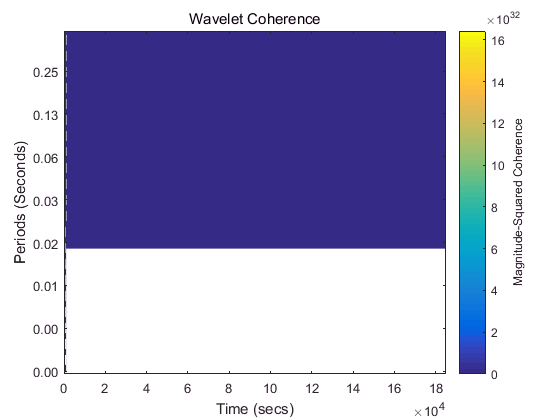

[wcoh, wcs, period, coi] = wcoherence(x, y, 'fs', Fs);
helperPlotCoherence(wcoh,t,period,coi,'Time (secs)','Periods (Seconds)');